#  DC Motor Dynamics

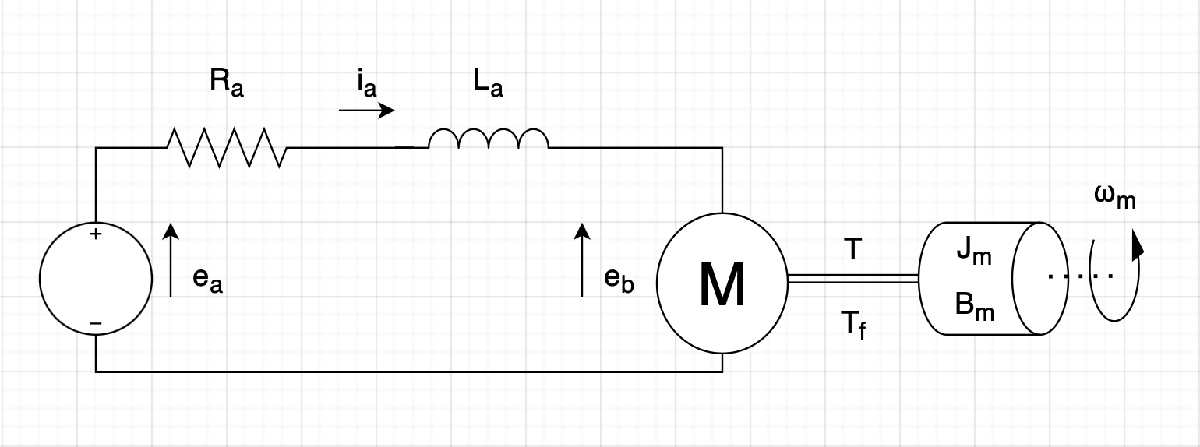

## SYSTEM IDENTIFICATION

Jm = 3.2284E-6;   % rotational inertia           [Nms^2/rad]
Bm = 3.5077E-6;   % vicous friction              [Nms/rad]
Kt = 0.0274;      % Motor Torque constant        []
Ke = 0.0274;      % Motor Back EMF constant      []
Ra = 4;           % armature resistance          [Ω]
La = 2.75E-6;     % armature inductance          [H]
gR = 12;          % gear ratio

%DC Motor Transfer Function
s = tf("s");
motor_tf = Kt/(s*((Jm*s+Bm)*(La*s+Ra)+(Kt*Ke)))
Ts = 5e-3;                               % Sample Time
dmotor_tf = c2d(motor_tf, Ts,'ZOH')     % Discreet TF of motor



motor_tf =
 
                    0.0274
  -------------------------------------------
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s
 
Continuous-time transfer function.
Model Properties


Cntrl = pid(Kp,Ki,Kd);                   % PID Controler TF
dCntrl = c2d(Cntrl,Ts,'tustin');         % Discreet PID TF


dmotor_tf =
 
   0.02408 z^2 + 0.02183 z + 7.46e-10
  -------------------------------------
  z^3 - 1.744 z^2 + 0.7437 z + 2.52e-21
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


sys_cl = feedback(dCntrl*dmotor_tf,1);   % Discreet System
dPlant = zpk(sys_cl)                     % Reagrange to Zero Pole Gain 


% Simulate the  response of the system 
pzmap(dPlant)
step(dPlant); title("Closed Loop Step Response")
[wn, zeta, poles_cl] = damp(dPlant);

% PID Tunner 
Cntrl = pidtune(dmotor_tf, 'PI')
pidTuner(dmotor_tf,Cntrl)

% Sys Id Motor